# Actividad 8.1 (Modelado Cinemático de Piernas)

### Jhonatan Yael Martinez Vargas

### Instrucciones:

**Obtener** la matriz de  transformación **homogénea  T ** de los siguientes sistemas la cual relacione la posición y orientación del extremo del robot respecto a su sistema de referencia fijo (la base).

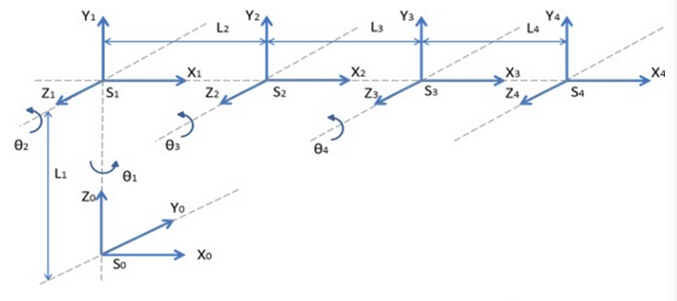

Dada la configuración propuesta en la imagen, lo primero que se debe de hacer es las matrices de transformación homogénea, para este caso se toma en cuenta que las longitudes ***"L1, L2, L3, L4" ***tienen la misma medida, en este caso 4 unidades.

clear all
close all
clc

%Calculamos las matrices de transformación homogénea
m_H0 = SE3

 

m_H0 = 
         1         0         0         0
         0         1         0         0
         0         0         1         0
         0         0         0         1


m_H1 = SE3(rotx(pi/2), [0,0,4])

 

m_H1 = 
         1         0         0         0
         0    0.9996   -0.0274         0
         0    0.0274    0.9996         4
         0         0         0         1


m_H2 = SE3(roty(0), [4,0,0])

 

m_H2 = 
         1         0         0         4
         0         1         0         0
         0         0         1         0
         0         0         0         1


m_H3 = SE3(roty(0), [4,0,0])

 

m_H3 = 
         1         0         0         4
         0         1         0         0
         0         0         1         0
         0         0         0         1


m_H4 = SE3(roty(0), [4,0,0])

 

m_H4 = 
         1         0         0         4
         0         1         0         0
         0         0         1         0
         0         0         0         1


Posteriormente lo que se realiza es definir a las matrices de transformacion globales, las cuales son el resultado del producto de dos tramas.

%Matriz de transformación homogenea global de 4 a 0 
m_H20 = m_H1 * m_H2

 

m_H20 = 
         1         0         0         4
         0    0.9996   -0.0274         0
         0    0.0274    0.9996         4
         0         0         0         1


m_H30 = m_H20 * m_H3

 

m_H30 = 
         1         0         0         8
         0    0.9996   -0.0274         0
         0    0.0274    0.9996         4
         0         0         0         1


m_H40 = m_H30 * m_H4

 

m_H40 = 
         1         0         0        12
         0    0.9996   -0.0274         0
         0    0.0274    0.9996         4
         0         0         0         1


Finalmente para temas de simulacion se establecen los limites del entorno en el cual se va deserrollar la simulación

plot3(0, 0, 0); axis([-6 6 -6 6 -6 6]); grid on;
hold on;

Se realizan las animaciones para cada una de las tramas:

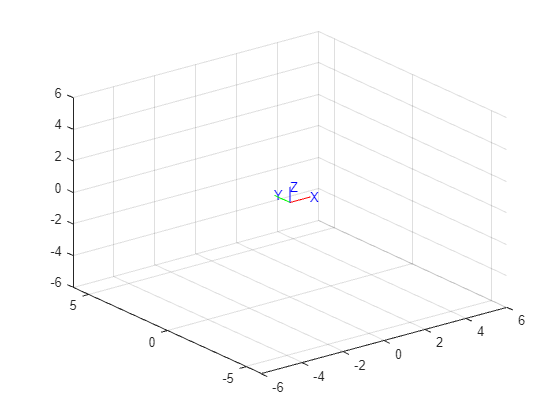

trplot(m_H0,'rgb','axis', [-6 6 -6 6 -6 6])

% Matriz de transformacion final
disp(m_H40)

    1         0         0        12
    0    0.9996  -0.02741         0
    0   0.02741    0.9996         4
    0         0         0         1


Aqui lo que se puede apreciar es el valor numerico que representa la matriz de transformacion final